# Automatic VOR Controller

## Set Up

clear;
global fi_flag_Simulink
newline = sprintf('\n');
fc_afc = struct();
fc_afc.altitude = 10000;
fc_afc.velocity = 500;
FC_flag = 1; % Trim for steady wings-level flight
thrust = 5000;          % thrust, lbs
elevator = -0.09;       % elevator, degrees
alpha = 8.49;              % AOA, degrees
rudder = -0.01;             % rudder angle, degrees
aileron = 0.01;            % aileron, degrees
disp('Trimming Low Fidelity Model AFC:');

Trimming Low Fidelity Model AFC:


fi_flag_Simulink = 0;
[trim_state_lo, trim_thrust_lo, trim_control_lo, dLEF, xu_lo] = trim_F16_Modified(thrust, elevator, alpha, aileron, rudder, fc_afc.velocity, fc_afc.altitude, FC_flag,9);

Trim Values and Cost:
cost   = 9.7227e-29
thrust = 2080.9182 lb
elev   = -2.252 deg
ail    = -6.5184e-15 deg
rud    = -3.0181e-14 deg
alpha  = 3.5973 deg
dLEF   = 0 deg
Vel.   = 500ft/s


trim_state_lin = trim_state_lo; trim_thrust_lin = trim_thrust_lo; trim_control_lin = trim_control_lo;
operating_point = operpoint('LIN_F16Block'); % retrieves initial conditions from integrators
operating_point.Inputs(1).u = trim_thrust_lin; operating_point.Inputs(2).u = trim_control_lin(1);
operating_point.Inputs(3).u = trim_control_lin(2); operating_point.Inputs(4).u = trim_control_lin(3);
SS_lo_VOR = linearize('LIN_F16Block');
long_states = [3 5 7 8 11 13 14];
long_inputs = [1 2];
long_outputs = [3 5 7 8 11];
SS_long_lo_VOR = ss(SS_lo_VOR.A(long_states,long_states), SS_lo_VOR.B(long_states,long_inputs), SS_lo_VOR.C(long_outputs,long_states), SS_lo_VOR.D(long_outputs,long_inputs));
SS_long_lo_VOR.StateName = SS_lo_VOR.StateName(long_states);
SS_long_lo_VOR.InputName= SS_lo_VOR.InputName(long_inputs);
lat_states = [4 6 7 9 10 12 13 15 16];
lat_inputs = [1 3 4];
lat_outputs = [4 6 7 9 10 12];
SS_lat_lo_VOR = ss(SS_lo_VOR.A(lat_states,lat_states), SS_lo_VOR.B(lat_states,lat_inputs), SS_lo_VOR.C(lat_outputs,lat_states), SS_lo_VOR.D(lat_outputs,lat_inputs));
SS_lat_lo_VOR.StateName = SS_lo_VOR.StateName(lat_states);
SS_lat_lo_VOR.InputName= SS_lo_VOR.InputName(lat_inputs);
disp(' ');

# Lateral State Space Reduced Model

disp('Lateral State Space');

Lateral State Space


lat_A_VOR = SS_lat_lo_VOR.A;
lat_C_VOR = SS_lat_lo_VOR.C;
lat_D_VOR = SS_lat_lo_VOR.D;
lat_A_VOR(7:9,:) = [];
lat_A_VOR(:,7:9) = [];
lat_A_VOR(3,:) = [];
lat_A_VOR(:,3) = [];
lat_B_VOR = SS_lat_lo_VOR.A(:,8:9);
lat_B_VOR(3,:) = [];
lat_B_VOR(6:8,:) = [];
lat_C_VOR(3,:) = [];
lat_C_VOR(:,7:9) = [];
lat_C_VOR(:,3) = [];
lat_D_VOR(:,1) = [];
lat_D_VOR(3,:) = [];
VOR_state_name = {'Phi' 'Psi' 'beta' 'p' 'r'};
VOR_input_name = {'d_a' 'd_r'};
VOR_output_name = {'Phi' 'Psi' 'beta' 'p' 'r'};
VOR_sys = ss(lat_A_VOR,lat_B_VOR,lat_C_VOR,lat_D_VOR,'statename',VOR_state_name,'inputname',VOR_input_name,'outputname',VOR_output_name)

VOR_sys =
 
  A = 
              Phi       Psi      beta         p         r
   Phi          0         0         0         1   0.06287
   Psi          0         0         0         0     1.002
   beta   0.06421         0   -0.2372   0.06291   -0.9922
   p            0         0    -25.23    -2.668    0.5802
   r            0         0     7.007  -0.03639   -0.3684
 
  B = 
               d_a        d_r
   Phi           0          0
   Psi           0          0
   beta  0.0002022  0.0005933
   p       -0.5373    0.07153
   r      -0.02952    -0.0549
 
  C = 
          Phi   Psi  beta     p     r
   Phi   57.3     0     0     0     0
   Psi      0  57.3     0     0     0
   beta     0     0  57.3     0     0
   p        0     0     0  57.3     0
   r        0     0     0     0  57.3
 
  D = 
         d_a  d_r
   Phi     0    0
   Psi     0    0
   beta    0    0
   p       0    0
   r       0    0
 
Continuous-time state-space model.


disp("")

# Tuning

s=tf('s');
G = tf(VOR_sys);
% roll rate control

tf_p_da = G(4,1)

tf_p_da =
 
  From input "d_a" to output "p":
     -30.79 s^3 - 19.92 s^2 - 259.4 s + 1.043
  ----------------------------------------------
  s^4 + 3.274 s^3 + 10.26 s^2 + 21.62 s + 0.2566
 
Continuous-time transfer function.
Model Properties


H_servo = 20.2/(s + 20.2);
tf_da_pc = H_servo*tf_p_da

tf_da_pc =
 
  From input "d_a" to output:
         -621.9 s^3 - 402.3 s^2 - 5240 s + 21.07
  -----------------------------------------------------
  s^5 + 23.47 s^4 + 76.39 s^3 + 229 s^2 + 437 s + 5.183
 
Continuous-time transfer function.
Model Properties


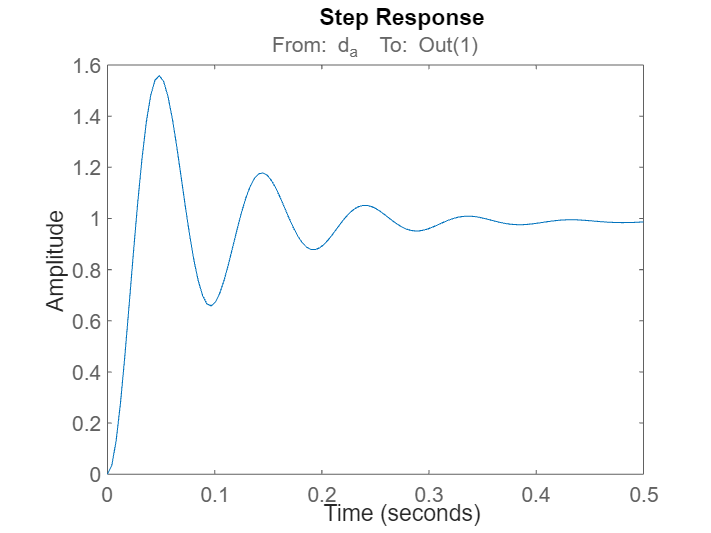


%sisotool(tf_da_pc);
K_p = -7; %selected for stability by making sure all poles of tf above lie on lhp using sisotool
step(feedback(K_p*tf_da_pc, 1)) %verify that this is the case



% roll angle control

% closed loop transfer function between roll rate and reference roll rate
tf_pc_p = minreal((K_p*tf_da_pc)/(1 + K_p*tf_da_pc));

tf_ol_roll_a = tf_pc_p * 1/s;
K_phi = 1 % since the responsed

K_phi = 1

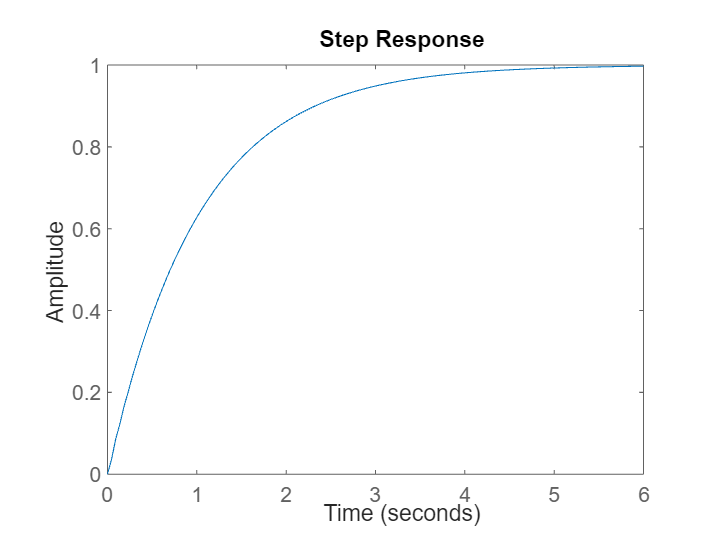


step(feedback(K_phi*tf_ol_roll_a,1))


% heading angle control
tf_phic_phi = minreal((K_phi*tf_pc_p*1/s)/(1+K_phi*tf_pc_p*1/s))

tf_phic_phi =
 
                  4353 s^3 + 2816 s^2 + 3.668e04 s - 147.5
  -------------------------------------------------------------------------
  s^6 + 23.47 s^5 + 4430 s^4 + 7398 s^3 + 3.993e04 s^2 + 3.654e04 s - 147.5
 
Continuous-time transfer function.
Model Properties



V0 = 500 * 0.3048

V0 = 152.4000

g = 9.80655

g = 9.8065

K_psi = 10

K_psi = 10

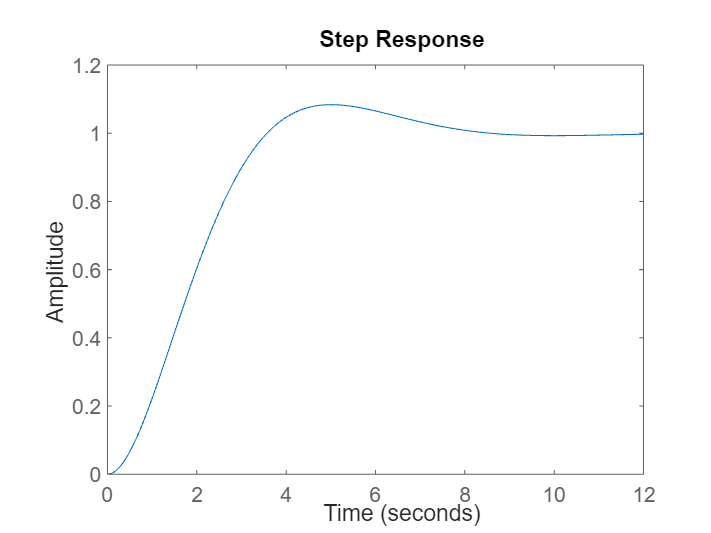


step(feedback(K_psi*tf_phic_phi * g/V0/s, 1))


% finding Kr
tf_r_dr = G(5,2)

tf_r_dr =
 
  From input "d_r" to output "r":
     -3.146 s^3 - 9.05 s^2 - 4.546 s - 3.253
  ----------------------------------------------
  s^4 + 3.274 s^3 + 10.26 s^2 + 21.62 s + 0.2566
 
Continuous-time transfer function.
Model Properties


tf_ol_rudder = H_servo*tf_p_da

tf_ol_rudder =
 
  From input "d_a" to output:
         -621.9 s^3 - 402.3 s^2 - 5240 s + 21.07
  -----------------------------------------------------
  s^5 + 23.47 s^4 + 76.39 s^3 + 229 s^2 + 437 s + 5.183
 
Continuous-time transfer function.
Model Properties


%sisotool(tf_ol_rudder)
K_r = -5

K_r = -5

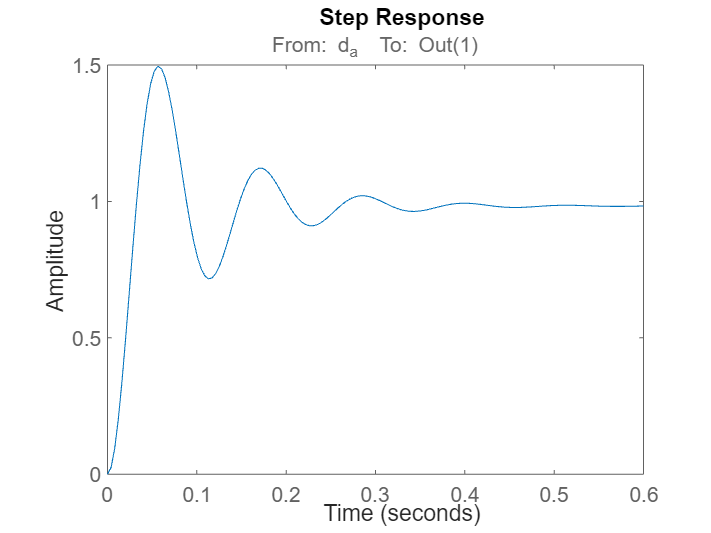

step(feedback(K_r*tf_ol_rudder,1))